num_img = 6200;

tic;
% path = 'archive';
% images = processImagesCeleb(path, num_img);
path = 'train2014';
images = processImagesCOCO(path, num_img);
test_seq = images(:,:,:,size(images,4)-19:size(images,4));
images = images(:,:,:,1:size(images,4)-20);

num_img = size(images,4);
images = arrayDatastore(images,IterationDimension=4);

time = toc;
disp(['Execution time: ' num2str(time) ' seconds']);

Execution time: 296.0745 seconds


Epochs = 40;
batch_size = 4;
LR = 1e-4;

VAE1_latent_dim = 400;
VAE2_latent_dim = 600;
VAE3_latent_dim = 800;

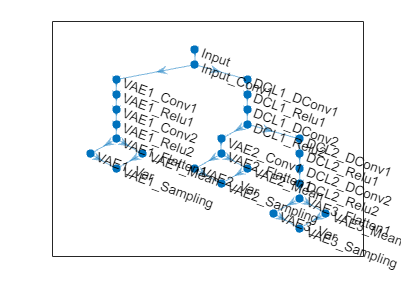

% Encoder
Encoder = layerGraph();
tempLayers = [
    imageInputLayer([288 352 3],"Name","Input","Normalization","none")
    convolution2dLayer([3 3], 16,"Name","Input_Conv1","WeightsInitializer","he")
    ];
Encoder = addLayers(Encoder,tempLayers);

% VAE1
tempLayers = [
    convolution2dLayer([3 3], 8,"Name","VAE1_Conv1","WeightsInitializer","he", "Stride",[2 2])
    reluLayer("Name","VAE1_Relu1")
    convolution2dLayer([1 1], 3,"Name","VAE1_Conv2","WeightsInitializer","he")
    reluLayer("Name","VAE1_Relu2")
    flattenLayer("Name","VAE1_Flatten1")
    fullyConnectedLayer(VAE1_latent_dim,"Name","VAE1_Var")];
Encoder = addLayers(Encoder,tempLayers);

tempLayers  =  fullyConnectedLayer(VAE1_latent_dim,"Name","VAE1_Mean");
Encoder = addLayers(Encoder,tempLayers);

tempLayers = CustomSamplingLayer( "Name", "VAE1_Sampling");
Encoder = addLayers(Encoder,tempLayers);

Encoder = connectLayers(Encoder,"VAE1_Flatten1","VAE1_Mean");
Encoder = connectLayers(Encoder,"VAE1_Var", "VAE1_Sampling/logVar");
Encoder = connectLayers(Encoder,"VAE1_Mean", "VAE1_Sampling/mu");
Encoder = connectLayers(Encoder,"Input_Conv1","VAE1_Conv1");

% DCL1
tempLayers = [
    convolution2dLayer([3 3], 16,"Name","DCL1_DConv1","DilationFactor", [2 2],"WeightsInitializer","he", "Stride",[2 2])
    reluLayer("Name","DCL1_Relu1")
    convolution2dLayer([3 3], 16,"Name","DCL1_DConv2","DilationFactor", [3 3],"WeightsInitializer","he", "Stride",[2 2])
    reluLayer("Name","DCL1_Relu2")
];

Encoder = addLayers(Encoder,tempLayers);

Encoder = connectLayers(Encoder,"Input_Conv1","DCL1_DConv1");

% VAE2
tempLayers = [
    convolution2dLayer([1 1], 3,"Name","VAE2_Conv1","WeightsInitializer","he")
    flattenLayer("Name","VAE2_Flatten1")
    fullyConnectedLayer(VAE2_latent_dim,"Name","VAE2_Var")];
Encoder = addLayers(Encoder,tempLayers);

tempLayers  =  fullyConnectedLayer(VAE2_latent_dim,"Name","VAE2_Mean");
Encoder = addLayers(Encoder,tempLayers);

tempLayers = CustomSamplingLayer( "Name", "VAE2_Sampling");
Encoder = addLayers(Encoder,tempLayers);

Encoder = connectLayers(Encoder,"VAE2_Flatten1","VAE2_Mean");
Encoder = connectLayers(Encoder, "VAE2_Var", "VAE2_Sampling/logVar");
Encoder = connectLayers(Encoder, "VAE2_Mean", "VAE2_Sampling/mu");

Encoder = connectLayers(Encoder, "DCL1_Relu2", "VAE2_Conv1");

% DCL2
tempLayers = [
    convolution2dLayer([3 3], 16,"Name","DCL2_DConv1","DilationFactor", [2 2],"WeightsInitializer","he", "Stride",[2 2])
    reluLayer("Name","DCL2_Relu1")
    convolution2dLayer([3 3], 16,"Name","DCL2_DConv2","DilationFactor", [3 3],"WeightsInitializer","he", "Stride",[2 2])
    reluLayer("Name","DCL2_Relu2")
];

Encoder = addLayers(Encoder,tempLayers);

Encoder = connectLayers(Encoder,"DCL1_Relu2","DCL2_DConv1");

% VAE3
tempLayers = [
    flattenLayer("Name","VAE3_Flatten1")
    fullyConnectedLayer(VAE3_latent_dim,"Name","VAE3_Var")];
Encoder = addLayers(Encoder,tempLayers);

tempLayers  =  fullyConnectedLayer(VAE3_latent_dim,"Name","VAE3_Mean");
Encoder = addLayers(Encoder,tempLayers);

tempLayers = CustomSamplingLayer( "Name", "VAE3_Sampling");
Encoder = addLayers(Encoder,tempLayers);

Encoder = connectLayers(Encoder,"VAE3_Flatten1","VAE3_Mean");
Encoder = connectLayers(Encoder, "VAE3_Var", "VAE3_Sampling/logVar");
Encoder = connectLayers(Encoder, "VAE3_Mean", "VAE3_Sampling/mu");
Encoder = connectLayers(Encoder, "DCL2_Relu2", "VAE3_Flatten1");

% clean up helper variable
clear tempLayers;

plot(Encoder);

Encoder = dlnetwork(Encoder);
% analyzeNetwork(Encoder)

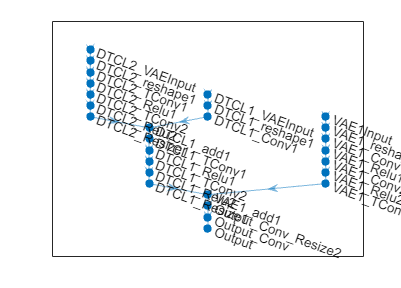

Decoder = layerGraph();

% VAE3 + DTCL2
tempLayers = [
    featureInputLayer(VAE3_latent_dim,"Name","DTCL2_VAEInput","Normalization","none")
    projectAndReshapeLayer([13 21 16], "Name","DTCL2_reshape1")
    transposedConv2dLayer([4 4], 16,"Name","DTCL2_TConv1", "Stride", [2 2])
    reluLayer("Name","DTCL2_Relu1")
    transposedConv2dLayer([4 4], 16,"Name","DTCL2_TConv2", "Stride", [2 2])
    reluLayer("Name","DTCL2_Relu2")
    resize2dLayer("Name","DTCL2_Resize1","GeometricTransformMode","half-pixel","Method","bilinear","NearestRoundingMode","round","OutputSize",[68 84])
    ];

Decoder = addLayers(Decoder,tempLayers);

% VAE2 + DTCL1
tempLayers = [
    featureInputLayer(VAE2_latent_dim,"Name","DTCL1_VAEInput","Normalization","none")
    projectAndReshapeLayer([68 84 3], "Name","DTCL1_reshape1")
    convolution2dLayer([1 1], 16,"Name","DTCL1_Conv1","WeightsInitializer","he")
    additionLayer(2,"Name","DTCL1_add1")
    transposedConv2dLayer([4 4], 16,"Name","DTCL1_TConv1", "Stride", [2 2])
    reluLayer("Name","DTCL1_Relu1")
    transposedConv2dLayer([4 4], 16,"Name","DTCL1_TConv2", "Stride", [2 2])
    reluLayer("Name","DTCL1_Relu2")
    resize2dLayer("Name","DTCL1_Resize1","GeometricTransformMode","half-pixel","Method","bilinear","NearestRoundingMode","round","OutputSize",[286 350])
    ];

Decoder = addLayers(Decoder,tempLayers);

Decoder = connectLayers(Decoder,"DTCL2_Resize1","DTCL1_add1/in2");

% VAE1
tempLayers = [
    featureInputLayer(VAE1_latent_dim,"Name","VAE1Input","Normalization","none")
    projectAndReshapeLayer([142 174 3], "Name","VAE1_reshape1")
    convolution2dLayer([1 1], 8,"Name","VAE1_Conv1","WeightsInitializer","he")
    reluLayer("Name","VAE1_Relu1")
    convolution2dLayer([1 1], 16,"Name","VAE1_Conv2","WeightsInitializer","he")
    reluLayer("Name","VAE1_Relu2")
    transposedConv2dLayer([4 4], 16,"Name","VAE1_TConv2", "Stride", [2 2])
    additionLayer(2,"Name","VAE1_add1")
    resize2dLayer("Name","Output_Conv_Resize2","GeometricTransformMode","half-pixel","Method","bilinear","NearestRoundingMode","round","OutputSize",[288 352])
    convolution2dLayer([1 1], 3,"Name","Output_Conv","WeightsInitializer","he")
    sigmoidLayer("Name", "Output")
    ];

Decoder = addLayers(Decoder,tempLayers);

Decoder = connectLayers(Decoder,"DTCL1_Resize1","VAE1_add1/in2");

% clean up helper variable
clear tempLayers;

plot(Decoder);

Decoder = dlnetwork(Decoder);
% analyzeNetwork(Decoder)

trailingAvgEncoder = [];
trailingAvgSqEncoder = [];

trailingAvgDecoder = [];
trailingAvgSqDecoder = [];

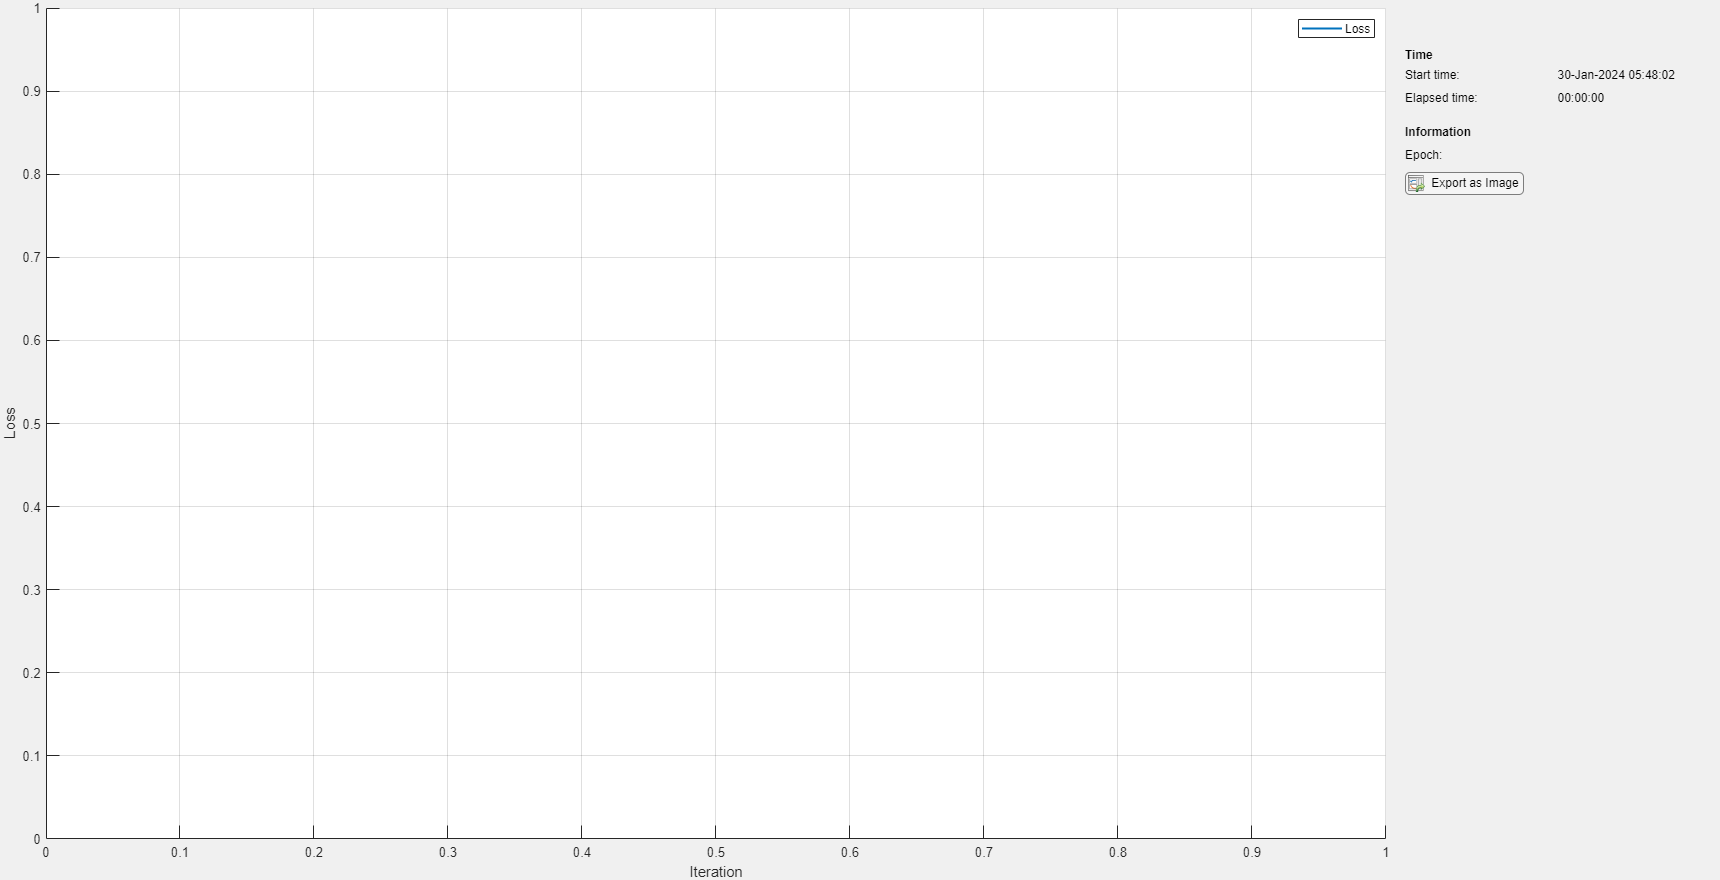

mbq = minibatchqueue(images,MiniBatchSize = batch_size, MiniBatchFormat = 'SSCB', OutputEnvironment = 'auto', PartialMiniBatch = 'discard');

Iter_Epoch = ceil(num_img / batch_size);
num_Iters = Epochs * Iter_Epoch;

monitor = trainingProgressMonitor( ...
    Metrics="Loss", ...
    Info="Epoch", ...
    XLabel="Iteration");

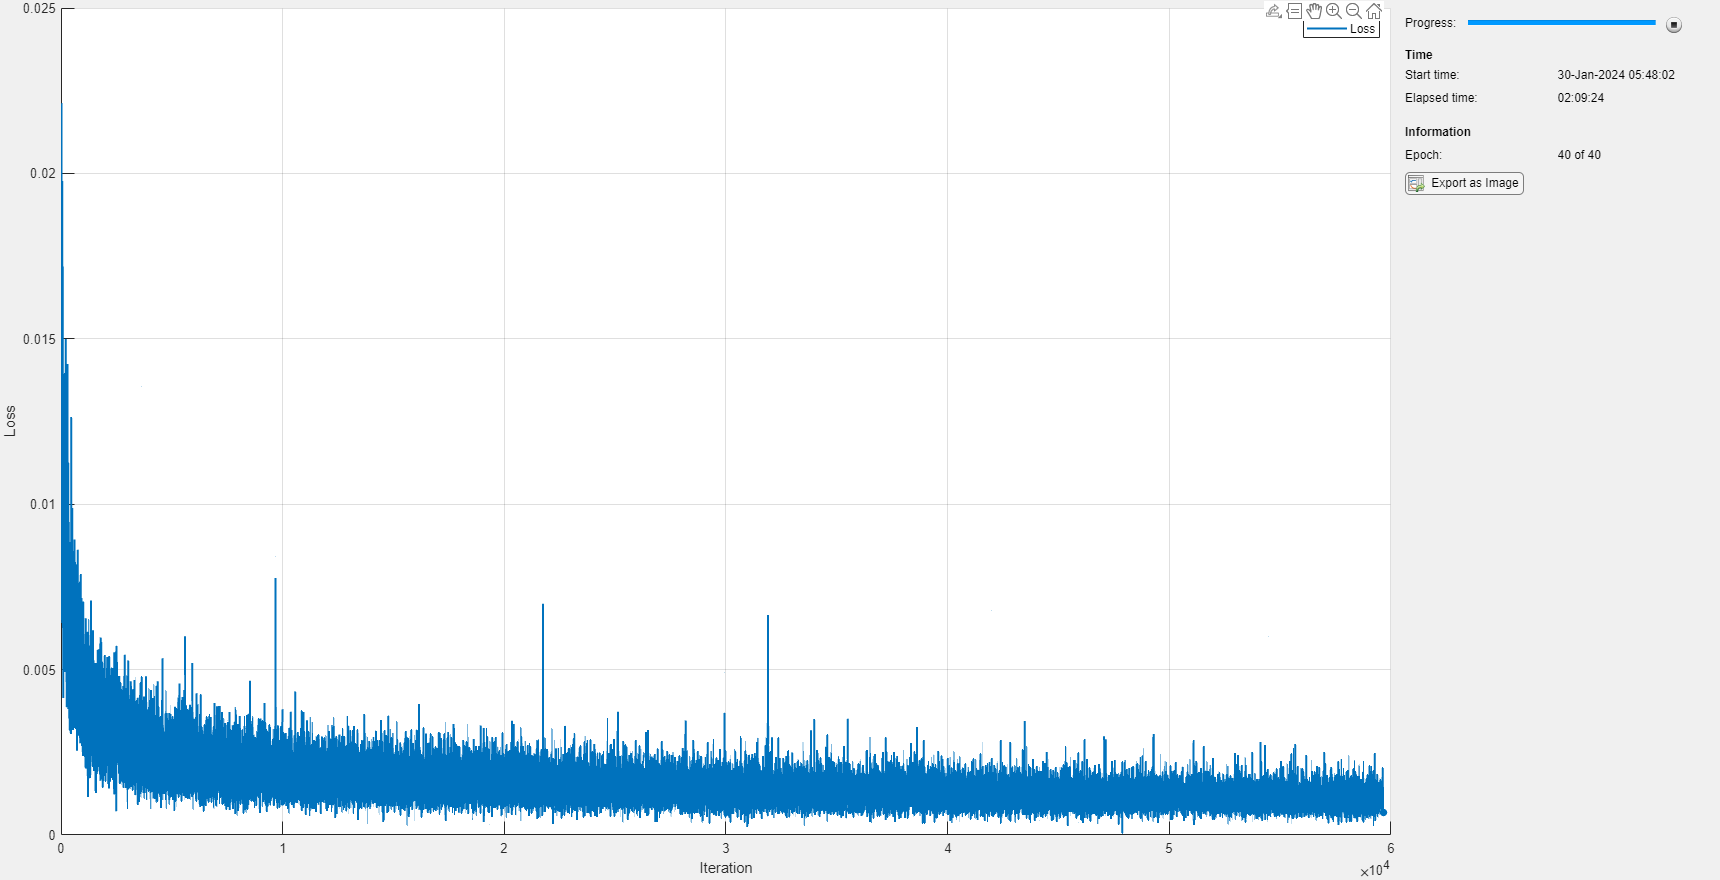

epoch = 0;
iter = 0;

% Loop over epochs.
while epoch < Epochs && ~monitor.Stop
    epoch = epoch + 1;

    % Shuffle data.
    shuffle(mbq);

    % Loop over mini-batches.
    while hasdata(mbq) && ~monitor.Stop
        iter = iter + 1;

        % Read mini-batch of data.
        X = next(mbq);
        
        [loss,gradEncoder, gradDecoder] = dlfeval(@modelLoss, Encoder, Decoder, X);

        % Update learnable parameters.
        [Encoder,trailingAvgEncoder,trailingAvgSqEncoder] = adamupdate(Encoder, ...
            gradEncoder,trailingAvgEncoder,trailingAvgSqEncoder,iter,LR);

        [Decoder, trailingAvgDecoder, trailingAvgSqDecoder] = adamupdate(Decoder, ...
            gradDecoder,trailingAvgDecoder,trailingAvgSqDecoder,iter,LR);

        % Update the training progress monitor. 
        recordMetrics(monitor,iter,Loss=loss);
        updateInfo(monitor,Epoch=epoch + " of " + Epochs);
        monitor.Progress = 100*iter/num_Iters;
    end
end

% save('DCL1.mat', "DCL1");
% save('VAE1.mat', "VAE1");
% save('DTCL1.mat', "DTCL1");
% save('Encoder.mat', "Encoder");
% save('Decoder.mat', "Decoder");

DCL1 = coder.loadDeepLearningNetwork('DCL1.mat');
VAE1 = coder.loadDeepLearningNetwork('VAE1.mat');
DTCL1 = coder.loadDeepLearningNetwork('DTCL1.mat');

Encoder = coder.loadDeepLearningNetwork('Encoder.mat');
Decoder = coder.loadDeepLearningNetwork('Decoder.mat');

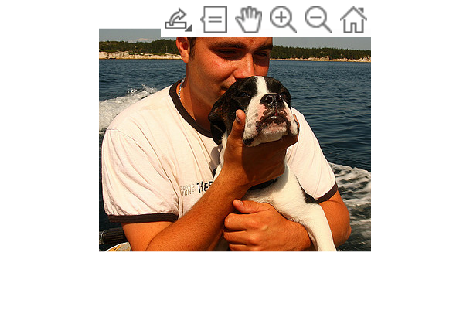

test_image = read(images);
test_image = cell2mat (test_image);
imshow(uint8(test_image * 255));

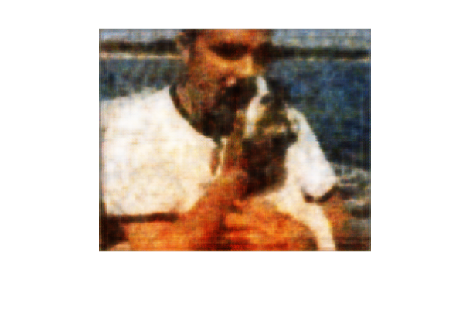


test_image = dlarray(test_image,  "SSCB");
[latent1, mu1, logVar1, latent2, mu2, logVar2, latent3, mu3, logVar3] = predict(Encoder, test_image);
X_hat = predict(Decoder, latent3, latent2, latent1);
rec_image = reshape(X_hat, [288, 352, 3]);
rec_image = extractdata(rec_image);
imshow(uint8(rec_image * 255))


PSNR = calcPSNR(extractdata(test_image) * 255, single(rec_image) * 255)

PSNR = 18.8094

SSIM = ssim(extractdata(test_image) * 255, single(rec_image) * 255)

SSIM = single
0.6045

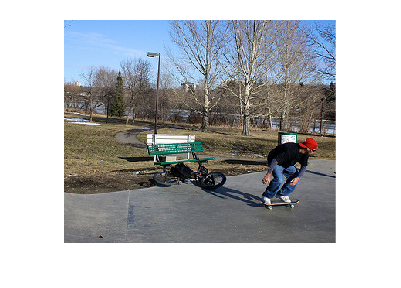

% foreman = imread('foreman20_40_RGB/foreman0024.bmp');
% foreman = imread('lena.tif');
foreman = test_seq(:,:,:,12)*255;

foreman = foreman(1:288,1:352,:);
imshow(uint8(foreman));

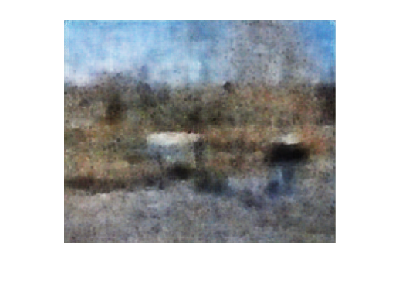


foreman_test = reshape(single(foreman) /255., 288, 352, 3, 1);
foreman_test = dlarray(foreman_test, "SSCB");

[latent1, mu1, logVar1, latent2, mu2, logVar2, latent3, mu3, logVar3] = predict(Encoder, foreman_test);
foreman_hat = predict(Decoder, latent3, latent2, latent1);

foreman_hat = reshape(foreman_hat, [288, 352, 3]);
foreman_hat = extractdata(foreman_hat);
foreman_hat = gather(foreman_hat);

imshow(uint8(foreman_hat * 255))

PSNR = calcPSNR(foreman_hat * 255, single(foreman))

PSNR = 17.7952

SSIM = ssim(foreman_hat * 255 * 255,single(foreman))

SSIM = single
3.9395e-05

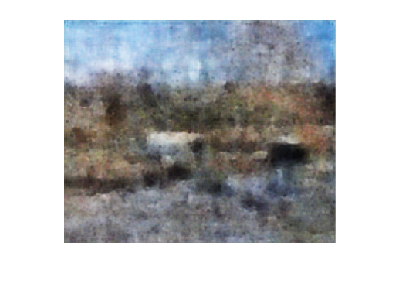

round_latent1 = dlarray(gpuArray(round(gather(extractdata(latent1)),0)), "CB");
round_latent2 = dlarray(gpuArray(round(gather(extractdata(latent2)),0)), "CB");
round_latent3 = dlarray(gpuArray(round(gather(extractdata(latent3)),0)), "CB");

foreman_hat_round = predict(Decoder, round_latent3, round_latent2, round_latent1);
foreman_hat_round = reshape(foreman_hat_round, [288, 352, 3]);
foreman_hat_round = extractdata(foreman_hat_round);
foreman_hat_round = gather(foreman_hat_round);

imshow(uint8(foreman_hat_round * 255))



PSNR = calcPSNR(foreman_hat_round * 255, single(foreman))

PSNR = 17.3442

SSIM = ssim(foreman_hat_round * 255 * 255,single(foreman))

SSIM = single
3.7123e-05

function PSNR = calcPSNR(Image, recImage)
    MSE = calcMSE(Image, recImage);
    PSNR = 10 * log10((2^8 - 1)^2 / MSE);
end

function MSE = calcMSE(Image, recImage)
    [H, W, C] = size(Image);
    diff = sum((double(Image) - double(recImage)).^2, "all");
    MSE = diff / (H * W * C);
end